# iDopaNeuro1 model generation

Driver to generate the iDN1 model generation results in "Mechanistic model-driven exometabolomic characterization of human dopaminergic neuronal metabolism"

 Note: The results are saved in the directory specified by each driver, currently the main results are saved in:

'~/work/sbgCloud/programReconstruction/projects/exoMetDN/results/codeResults/iDN1'

## XomicsToModel data preparation

### Recon 3D

Preparation of the generic Recon3D model with thermodynamic data, information on formed and broken bonds, and addition of names in somereactions. It excludes the expression of the reactions because that is specific information which it is included in XomicsToModel.

The generic model is saved in :

'~/work/sbgCloud/programExperimental/projects/xomics/data/Recon3D_301/Recon3DModel_301_xomics_input.mat'

driver_prepareRecon3Model

The transcriptomic data is ready
The exometabolomic data is ready


### Specific data preprocessing

The tables transcriptomicsData and exoMet, which are used in the variable specificData, are generated using the function transcriptomics2genes and loading the exometabolomic data.

The external files are saved in:

~/work/sbgCloud/programReconstruction/projects/exoMetDN/data/xomics

driver_specificDataPreprocessing

Reading inputData from : ~/work/sbgCloud/programReconstruction/projects/exoMetDN/data/xomics/bibliomicData.xlsx
Reading sheet: activeGenes
Reading sheet: activeReactions
Reading sheet: cellCultureData
Reading sheet: coupledRxns
Reading sheet: essentialAA
Reading sheet: inactiveGenes
Reading sheet: mediaData
Reading sheet: presentMetabolites
Reading sheet: rxns2add
Reading sheet: rxns2constrain
Reading sheet: rxnsHypothesis
Reading sheet: rxns2remove
Reading sheet: sinkDemand
Generating models ...

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on the following mac OS versions: macOS 10.13+.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2021a.
Models saved in:


modelsDir = '~/work/sbgCloud/programReconstruction/projects/exoMetDN/results/multidimensionalModelGeneration'

## iDN1 model generation

Generate iDopaNeuro model conditions with different conditions using the unction `XomicsToMultipleModels`. The current conditions are

- Generic model: Recon3DModel_301_xomics_input

- cobraSolver: gurobi

- tissueSpecificSolver: fastCore - thermoKernel

- activeGenesApproach: deleteModelGenes - oneRxnPerActiveGene

- transcriptomicThreshold: [0 2]

- limitBounds: [1e3 1e4]

- inactiveGenesTranscriptomics: [true false]

- closeIons: [true false]

- curationOverOmics: [true false]

The models are saved in:

~/work/sbgCloud/programReconstruction/projects/exoMetDN/results/codeResults/multidimensionalModelGeneration

driver_createMultipleIDNModels

Model's predictive capacity tested
Results saved in:
~/work/sbgCloud/programReconstruction/projects/exoMetDN/results/codeResults/iDN1/multidimensionalComparisonStats.mat


The predictive capacity of each model generated by driver_createMultipleIDNModels is evaluated using the modelPredictiveCapacity function to ifentify the model with the highest score. The features to consider are the flux consistency of reactions and metabolites, the predictive capacity of uptakes and secretions, the Euclidean distance to the experimental values, the number of metabolites, and the number of reactions. Save the results as accuracy.mat in each directory

The models are saved in:

~/work/sbgCloud/programReconstruction/projects/exoMetDN/results/codeResults/multidimensionalModelGeneration

iDopaNeuro1ValidationTable = 6×2 table
                           unWeightedTCBMflux    unWeightedTCBMfluxConc
                           __________________    ______________________

    qualitativeBoth               0.74                    0.74         
    qualitativeModelSec           0.95                    0.95         
    qualitativeModelUpt           0.64                    0.64         
    spearmanBoth                  0.55                    0.57         
    spearmanModelSec              0.47                    0.49         
    spearmanModelUpt              0.16                    0.08         


iDopaNeuro1p1ValidationTable = 6×2 table
                            unWeightedTCBMflux    unWeightedTCBMfluxConc
                            __________________    ______________________

    qualitativeBoth                0.73                    0.62         
    qualitativeModelSec            0.95                    0.91         
    qualitativeModelUpt            0.61                    0.48         
    quantitativeBoth               0.44                    0.53         
    quantitativeModelSec           0.55                    0.46         
    quantitativeModelUpt           0.41                    0.36         


bestModelsTable = 5×2 table
                                   iDopaNeuro1Core     iDopaNeuro1ConditionType
                                  _________________    ________________________

    Metabolites                                 908                    1393    
    Reactions                                  1399                    2210    
    Rank of S                                   837                    1303    
    Qualitative                   0.742424242424242       0.727272727272727    
    Quantitative (μmol/gDW/hr)    0.574489795918367       0.436960600375235    


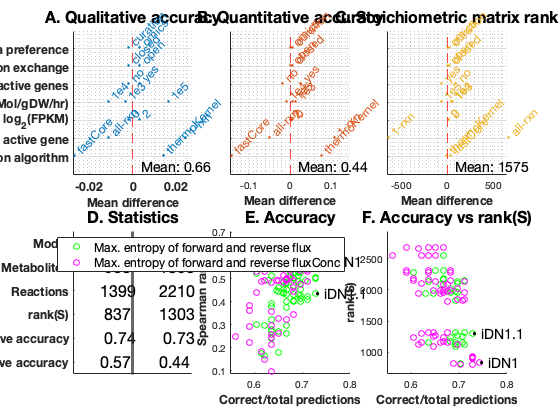

driver_testiDNmodelPredictiveCapacity

Identify the most accurate model based on the results of `driver_testiDNmodelPredictiveCapacity.m`. The information gathered from each model is used to identify two sets of conditions:

- The most accurate model

- The mos accurate conditions

- The most accurate objective functions

The models are saved in:

~/work/sbgCloud/programReconstruction/projects/exoMetDN/results/codeResults/iDN1

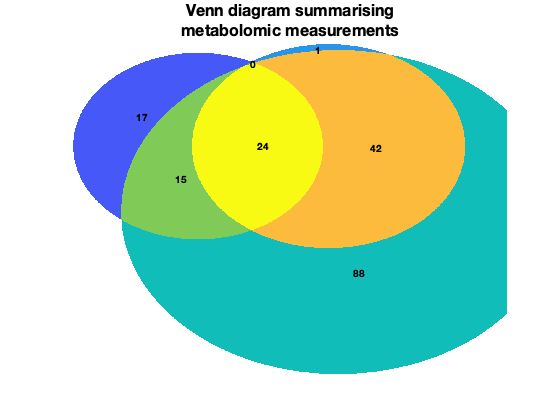

driver_identifyMostAccurateiDNModel

## Statistics 

Group the exchange reactions of the most accurate model

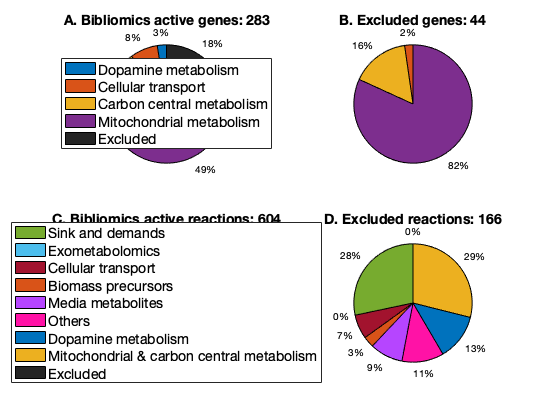

driver_vennMetabolites

Identify active reactions and genes in the model


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on the following mac OS versions: macOS 10.13+.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2021a.
---Non-convex approximation---
394 of these are heuristically minimal rxns.
392 of these are essential rxns.


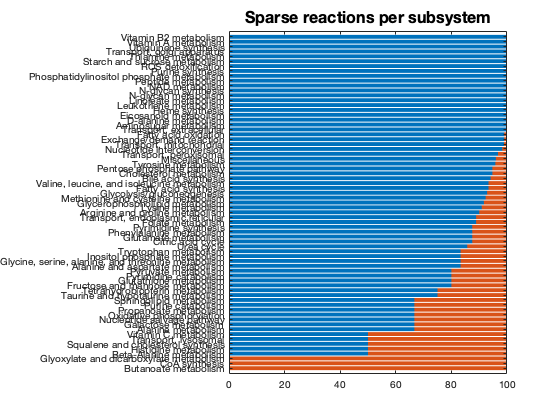

driver_actinveInactiveGenesRxns

## Sparse FBA

The driver generates a graph comparing the fraction of reactions in and out of the minimal flux vector in each metabolic subsystem of the iDopaNeuro1 model.

Reaction 1/20 selected
Reaction 2/20 selected
Reaction 3/20 selected
Reaction 4/20 selected
Reaction 5/20 selected
Reaction 6/20 selected
Reaction 7/20 selected
Reaction 8/20 selected
Reaction 9/20 selected
Reaction 10/20 selected
Reaction 11/20 selected
Reaction 12/20 selected
Reaction 13/20 selected
Reaction 14/20 selected
Reaction 15/20 selected
Reaction 16/20 selected
Reaction 17/20 selected
Reaction 18/20 selected
Reaction 19/20 selected
Reaction 20/20 selected


    {'CYSTS_H2S'}

[mosek] Primal optimality condition in solveCobraEP not satisfied, residual = 0.00046916, while problem feasTol = 0.0001.  origStat = OPTIMAL


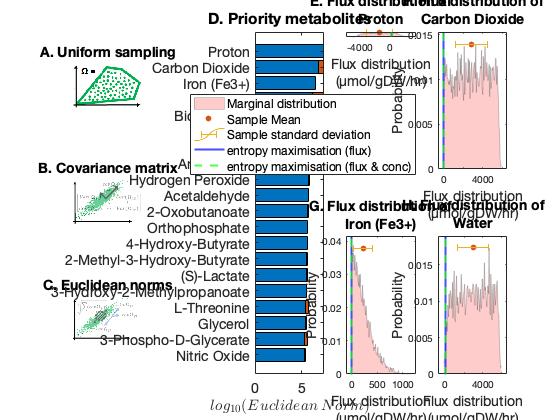

driver_sparseFBA

## Uncertainty reduction

Uniform sampling of feasible solution space, was used to predict a set of metabolites that could potentially be secreted by the iDN model. In principle, all of these metabolites should be considered for targeted metabolomic analyses in exometabolomic experiments.

Using existing internal net flux bounds without modification.


    {'CYSTS_H2S'}

Using existing external net flux bounds without modification.
[mosek] Primal optimality condition in solveCobraEP not satisfied, residual = 0.0001532, while problem feasTol = 0.0001.  origStat = OPTIMAL

Optimality conditions (biochemistry)
 0.00015 || N*(vf - vr) + B*ve - x + x0 - b ||_inf
 0.00014 || k_vf - g + cf + ci + N'*y_N + C'*y_C + y_v - z_vf + y_vt ||_inf
 8.9e-11 || k_vr - g + cr - ci - N'*y_N - C'*y_C - y_v -  z_vr + y_vt ||_inf
 5.6e-11 || k_x  + u0 - y_N + z_dx + z_x  + y_xt ||_inf
 5.7e-11 || k_x0 + u0 + y_N - z_dx + z_x0 + y_x0t ||_inf
       0 || k_1 + z_t ||_inf
 3.6e-11 || k_e_vf - g - z_t_f ||_inf
 3.6e-11 || k_e_vr - g  - z_t_r ||_inf
 5.3e-12 || k_tx - f  - z_t_x ||_inf
 5.3e-12 || k_tx0 - f - z_t_x0 ||_inf
 5.7e-05 || t_f + vf*log(vf/(1'*(vf + vr))) ||_inf
 3.5e-05 || t_r + vr*log(vr/(1'*(vf + vr))) ||_inf
 3.6e-07 || t_x + x*log(x/(1'*x)) ||_inf
 3.7e-07 || t_x0 + x0*log(x0/(1'*x0)) ||_inf

Derived optimality conditions (fluxes)
  0.0005 || g.

    {'CYSTS_H2S'}

Using existing external net flux bounds without modification.
[mosek] Primal optimality condition in solveCobraEP not satisfied, residual = 0.0001532, while problem feasTol = 0.0001.  origStat = OPTIMAL

Optimality conditions (biochemistry)
 0.00015 || N*(vf - vr) + B*ve - x + x0 - b ||_inf
 0.00014 || k_vf - g + cf + ci + N'*y_N + C'*y_C + y_v - z_vf + y_vt ||_inf
 8.9e-11 || k_vr - g + cr - ci - N'*y_N - C'*y_C - y_v -  z_vr + y_vt ||_inf
 5.6e-11 || k_x  + u0 - y_N + z_dx + z_x  + y_xt ||_inf
 5.7e-11 || k_x0 + u0 + y_N - z_dx + z_x0 + y_x0t ||_inf
       0 || k_1 + z_t ||_inf
 3.6e-11 || k_e_vf - g - z_t_f ||_inf
 3.6e-11 || k_e_vr - g  - z_t_r ||_inf
 5.3e-12 || k_tx - f  - z_t_x ||_inf
 5.3e-12 || k_tx0 - f - z_t_x0 ||_inf
 5.7e-05 || t_f + vf*log(vf/(1'*(vf + vr))) ||_inf
 3.5e-05 || t_r + vr*log(vr/(1'*(vf + vr))) ||_inf
 3.6e-07 || t_x + x*log(x/(1'*x)) ||_inf
 3.7e-07 || t_x0 + x0*log(x0/(1'*x0)) ||_inf

Derived optimality conditions (fluxes)
  0.0005 || g.

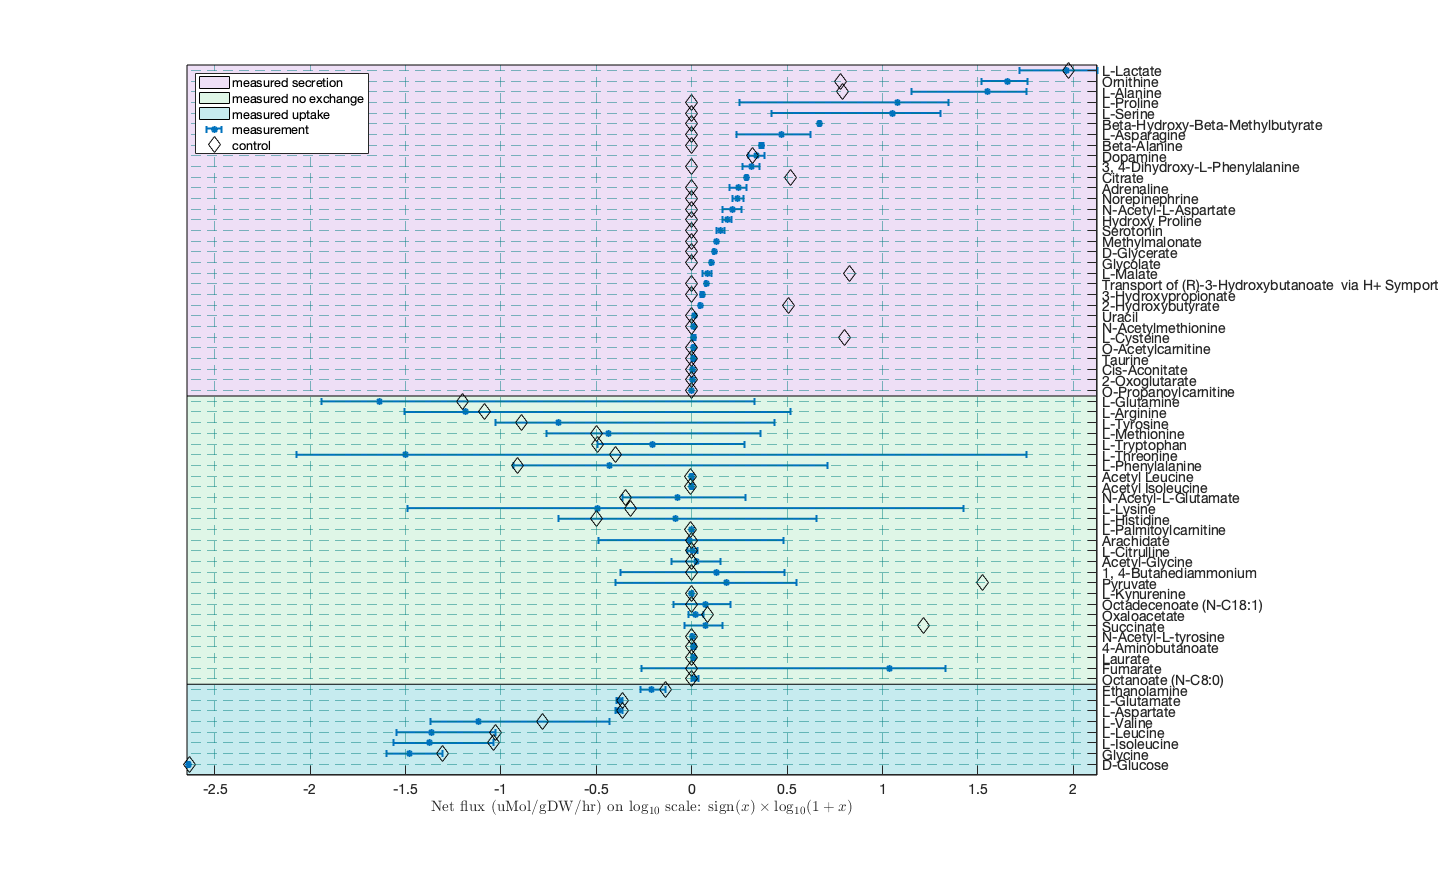

Using existing internal net flux bounds without modification.


    {'CYSTS_H2S'}

Using existing external net flux bounds without modification.
[mosek] Primal optimality condition in solveCobraEP not satisfied, residual = 0.0001532, while problem feasTol = 0.0001.  origStat = OPTIMAL

Optimality conditions (biochemistry)
 0.00015 || N*(vf - vr) + B*ve - x + x0 - b ||_inf
 0.00014 || k_vf - g + cf + ci + N'*y_N + C'*y_C + y_v - z_vf + y_vt ||_inf
 8.9e-11 || k_vr - g + cr - ci - N'*y_N - C'*y_C - y_v -  z_vr + y_vt ||_inf
 5.6e-11 || k_x  + u0 - y_N + z_dx + z_x  + y_xt ||_inf
 5.7e-11 || k_x0 + u0 + y_N - z_dx + z_x0 + y_x0t ||_inf
       0 || k_1 + z_t ||_inf
 3.6e-11 || k_e_vf - g - z_t_f ||_inf
 3.6e-11 || k_e_vr - g  - z_t_r ||_inf
 5.3e-12 || k_tx - f  - z_t_x ||_inf
 5.3e-12 || k_tx0 - f - z_t_x0 ||_inf
 5.7e-05 || t_f + vf*log(vf/(1'*(vf + vr))) ||_inf
 3.5e-05 || t_r + vr*log(vr/(1'*(vf + vr))) ||_inf
 3.6e-07 || t_x + x*log(x/(1'*x)) ||_inf
 3.7e-07 || t_x0 + x0*log(x0/(1'*x0)) ||_inf

Derived optimality conditions (fluxes)
  0.0005 || g.

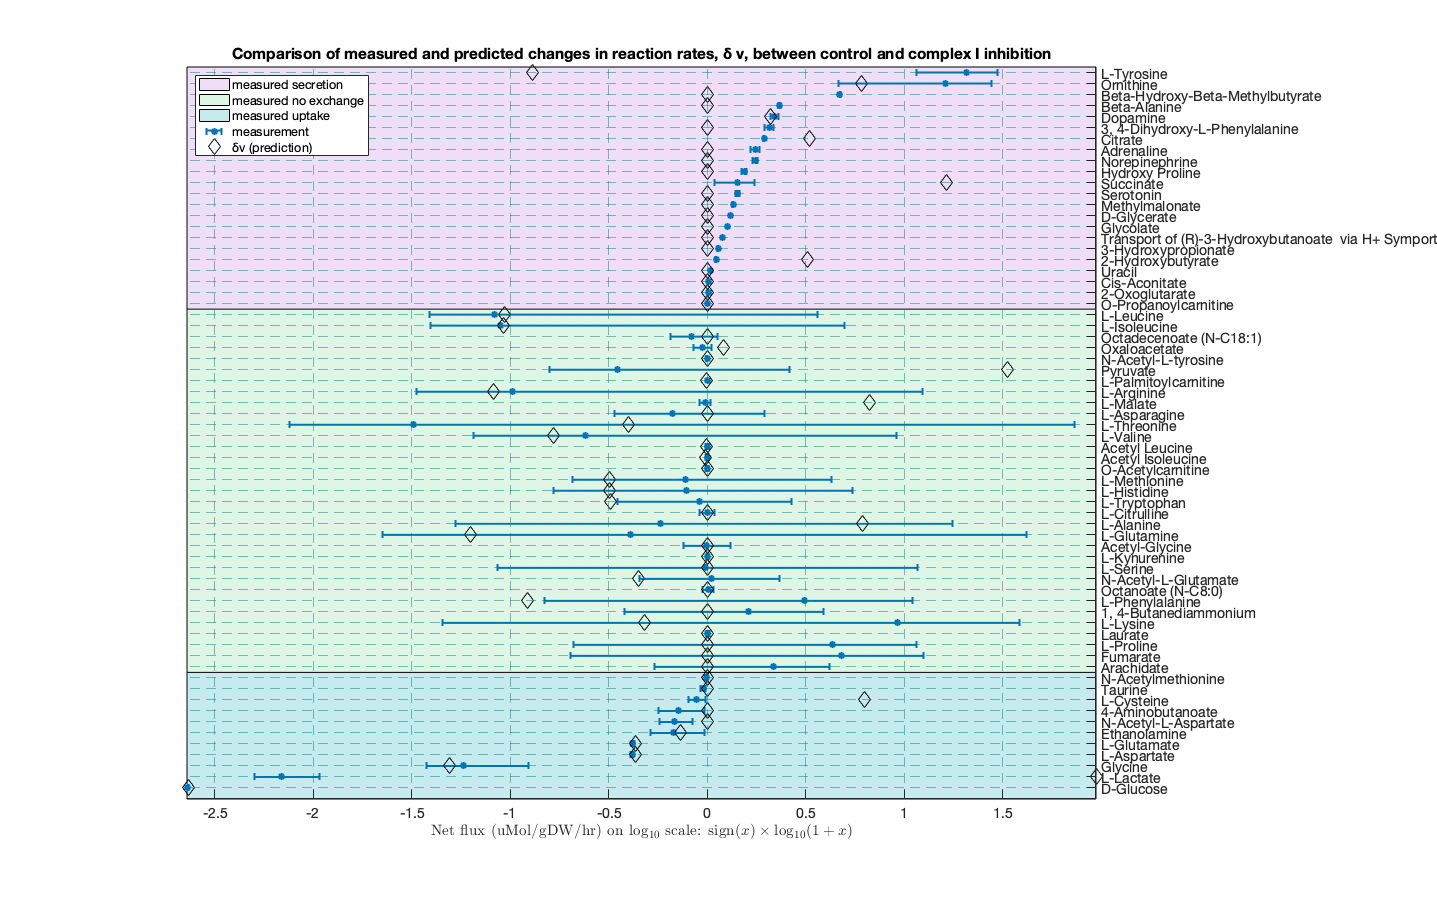

driver_uncertaintyReduction

## Perturbation analysis

driver_GBA1prediction